# **Plate mode with respect to THICKNESS**

**2024-01-18 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

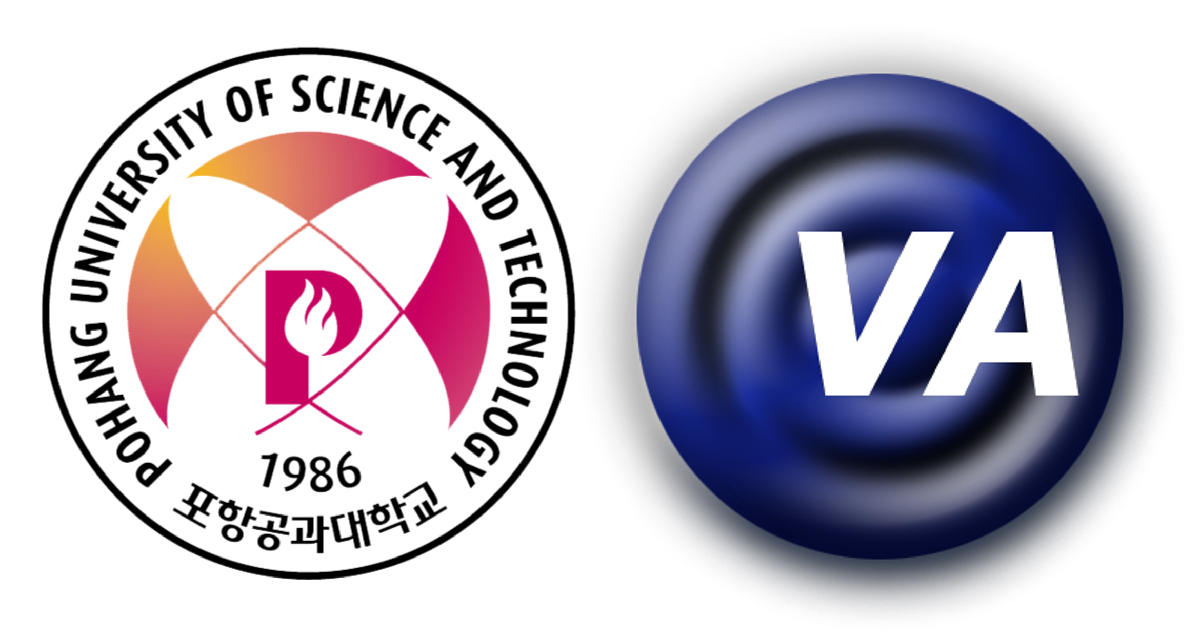

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

close all
clf 
clear

Env.MPH.PATH    = 'D:\wj\Back Up\0 -Doctoral research\M - MATLAB - SPPALs\';
Env.FIG.UNIT    = 'inches';
Env.FIG.WIDTH   = 3.25;
Env.FIG.HEIGHT  = 2.5;

Study.FREQ_START    = 60e3;
Study.FREQ_STOP     = 90e3;
Study.FREQ_STEP_SOLID ...
                    = 10;
Study.FREQ_STEP_ACO ...
                    = 100;
Study.freqSolid     = Study.FREQ_START:Study.FREQ_STEP_SOLID:Study.FREQ_STOP;
Study.freqAcoustic  = Study.FREQ_START:Study.FREQ_STEP_ACO:Study.FREQ_STOP;

Study.MODE_NO_START = 4;
Study.MODE_NO_STOP  = 9;
Study.mode          = Study.MODE_NO_START:Study.MODE_NO_STOP;
Study.nMode         = length(Study.mode);

Study.Z_START       = 0.1;
Study.Z_STOP        = 2;
Study.N_Z           = 1000;

Study.TH_START      = -90/180*pi;
Study.TH_STOP       = 90/180*pi;
Study.N_TH          = 361;

% Mode:                 1   2   3   4   5   6   7   8   9                        
Study.Opt.lowerBound = [1   1   1   1.3 1.1 1.1 1   1   1];
Study.Opt.upperBound = [1.5 1.5 1.5 1.4 1.3 1.2 1.2 1.1 1.1];

% Load the material properties
Mat = import_material('materials_OBS_loss_D.txt')

Mat = 4×14 table
                              Mat           rho             Y33                    Y11             nu      Q      eps33      d33        g33       k33        d31        DF            v3                v1      
                       _________________    ____    ___________________    ___________________    ____    ____    _____    ________    ______    _____    _________    _____    ______________    ______________

    Aluminum           "Aluminum"           2780    7.2e+10+3.6e+07i   


%%
Air.c = 343;
Air.rho = 1.21;
%%

Plate.FREQ = 75e3;
Plate.RADIUS = 50e-3;
Plate.THICKNESS = 1e-3;
Plate.LAMBDA = [3.01146
                6.20540
                9.37084
                12.52518
                15.67466
                18.82161
                21.96703
                25.11160
                28.25549
                31.39893
                34.54204
                37.63490
                40.82757
                43.97008
                47.11248
                50.25478];
Plate.tStep = Air.c/Plate.FREQ/2; %%





$$$f_i = \frac{\lambda_i^2t}{2\pi r^2} \sqrt{\frac{E}{12\rho(1-\nu^2)}}$$$


Itao, K. and S.H. Crandall, Natural Modes and Natural Frequencies of Uniform, Circular, Free-Edge Plates. Journal of Applied Mechanics, 1979. 46(2): p. 448-453.

computePlateFreq       = @(r, t, LAMBDA, rho, E, nu) LAMBDA^2*t/(2*pi*r^2)*sqrt(E/(12*rho*(1-nu^2)));


$$$r = \sqrt{\frac{\lambda_i^2t}{2\pi} \sqrt{\frac{E}{12\rho(1-\nu^2)}}}$$$


computePlateRadius      = @(freq, t, LAMBDA, rho, E,  nu) sqrt((LAMBDA^2*t)/(2*pi*freq)*sqrt(E/(12*rho*(1-nu^2))));


$$$t = \frac{2\pi f_i r^2}{\lambda_i^2} \sqrt{\frac{12\rho(1-\nu^2)}{E}}$$$


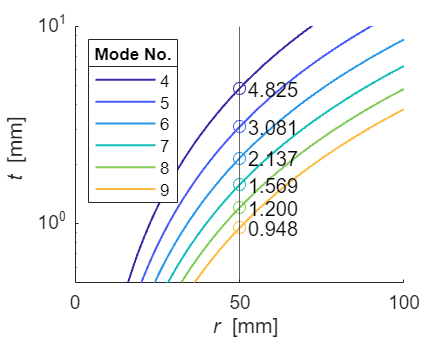

computePlateThickness   = @(freq, r, LAMBDA, rho, E, nu) freq*(2*pi*r.^2)/(LAMBDA^2)/sqrt(E/(12*rho*(1-nu^2)));

t = 0:1e-5:2e-3;
Plate.rCPT = zeros(length(t),Study.nMode);
r = 0:1e-3:100e-3;
Plate.tCPT = zeros(length(r),Study.nMode);

for iMode = 1:Study.nMode
    Plate.rCPT(:,iMode) = computePlateRadius(Plate.FREQ, t, Plate.LAMBDA(Study.mode(iMode)), ...
        Mat.rho('Aluminum'), abs(Mat.Y33('Aluminum')), Mat.nu('Aluminum'));
    Plate.tCPT(:,iMode) = computePlateThickness(Plate.FREQ, r, Plate.LAMBDA(Study.mode(iMode)), ...
        Mat.rho('Aluminum'), abs(Mat.Y33('Aluminum')), Mat.nu('Aluminum'));
end

figurePlateThickness = figure('Name','r vs. t','Units',Env.FIG.UNIT, ...
    'OuterPosition',[0 0 Env.FIG.WIDTH Env.FIG.HEIGHT]);
% figurePlateThickness = figure('Name','r vs. t');
axesPlateThickness = axes('Parent',figurePlateThickness);
hold(axesPlateThickness,'on');
C = colororder(parula(Study.nMode+1));
colororder(C(1:Study.nMode,:));

xline(Plate.RADIUS*1e3)
pPlateThickness = plot(r*1e3,Plate.tCPT*1e3,'LineWidth',1);

Plate.tCPT = Plate.tCPT(find(r == Plate.RADIUS),:);
sPlateThickness = scatter(Plate.RADIUS*1e3, Plate.tCPT*1e3);
text(repmat(Plate.RADIUS,Study.nMode,1)*1.05e3, Plate.tCPT*1e3, arrayfun(@(x) num2str(x*1e3,'%.3f'), Plate.tCPT, 'UniformOutput', false))

xlabel('{\it r} [mm]')
ylabel('{\it t} [mm]')
ylim(axesPlateThickness,[0.5 10]);
set(axesPlateThickness,'YMinorTick','on','YScale','log');
lgdPlateThickness = legend(pPlateThickness, string(Study.MODE_NO_START:Study.MODE_NO_STOP),'Location','northwest','Orientation','vertical');
title(lgdPlateThickness, 'Mode No.')
hold(axesPlateThickness,'off');

if exist('modelComputePlateThickness','var') ~= 1
    modelComputePlateThickness = mphload('computePlateThickness.mph');
end
modelComputePlateThickness.hist.disable;

modelComputePlateThickness.param.set('Plate_freq',   [num2str(Plate.FREQ)      ' [Hz]']);
modelComputePlateThickness.param.set('Plate_r',      [num2str(Plate.RADIUS)    ' [m]']);

Plate.tFEM = zeros(1,Study.nMode);
Plate.rStepFEM = cell(1, Study.nMode);

for iMode = 1:Study.nMode
    tic
    modelComputePlateThickness.param.set('Plate_tIV',           [num2str(Plate.tCPT(iMode)) ' [m]']);
    modelComputePlateThickness.param.set('Study_Opt_lowerBound',num2str(Study.Opt.lowerBound(Study.mode(iMode))));
    modelComputePlateThickness.param.set('Study_Opt_upperBound',num2str(Study.Opt.upperBound(Study.mode(iMode))));
    mphrun(modelComputePlateThickness,'std1')
    Plate.tFEM(iMode) = mphglobal(modelComputePlateThickness, 'Plate_t', 'dataset', 'dset1');
    Plate.freqFEM(iMode) = mphglobal(modelComputePlateThickness, 'abs(freq)', 'dataset', 'dset1');
    
    [tempR, tempZ] = meshgrid(0:1e-4:Plate.RADIUS,0);
    tempCoord = [tempR(:) tempZ(:)]';
    tempW = real(mphinterp(modelComputePlateThickness, 'w', 'coord', tempCoord));
    iZeroCrossing = find(tempW(1:end-1).*tempW(2:end) <= 0);
    tempRZeroCrossing = tempR(iZeroCrossing);

    Plate.rStepFEM(iMode) = mat2cell(tempRZeroCrossing',length(tempRZeroCrossing),1);
    toc
end

Elapsed time is 50.506210 seconds.
Elapsed time is 44.760060 seconds.
Elapsed time is 35.784430 seconds.
Elapsed time is 43.771052 seconds.
Elapsed time is 35.448400 seconds.
Elapsed time is 38.650265 seconds.


% Mode  r_{CPT} r_{FEM} RE      RE      freq
%                       ↳ Relative error from CPT to FEM
%                               ↳ Relative error from FEM to CPT
% 1     [mm]    [mm]    [%]     [%]     [kHz]
disp([Study.mode' Plate.tCPT'*1e3 Plate.tFEM'*1e3 (Plate.tCPT-Plate.tFEM)'./Plate.tFEM'*1e2 (Plate.tFEM-Plate.tCPT)'./Plate.tCPT'*1e2 Plate.freqFEM'/1e3])

    4.0000    4.8253    6.6894  -27.8672   38.6332   74.9994
    5.0000    3.0810    3.7309  -17.4188   21.0929   75.0010
    6.0000    2.1369    2.4274  -11.9683   13.5955   74.9965
    7.0000    1.5687    1.7191   -8.7489    9.5877   75.0011
    8.0000    1.2004    1.2867   -6.7020    7.1835   75.0223
    9.0000    0.9482    1.0008   -5.2555    5.5471   75.0080



if exist('modelComputePlateImpedance','var') ~= 1
    modelComputePlateImpedance = mphload('computePlateImpedance.mph');
end
modelComputePlateImpedance.hist.disable;

modelComputePlateImpedance.param.set('Study_freqStart',   [num2str(Study.FREQ_START)    ' [Hz]']);
modelComputePlateImpedance.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_SOLID)     ' [Hz]']);
modelComputePlateImpedance.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)     ' [Hz]']);
modelComputePlateImpedance.param.set('Plate_r',           [num2str(Plate.RADIUS)        ' [m]']);

Plate.zPlateFEM = zeros(length(Study.freqSolid),Study.nMode);
for iMode = 1:Study.nMode
    tic
    modelComputePlateImpedance.param.set('Plate_t',       [num2str(Plate.tFEM(iMode)) ' [m]']);
    mphrun(modelComputePlateImpedance,'std1')
    Plate.zPlateFEM(:,iMode) = mphevalpoint(modelComputePlateImpedance, '1[N]/solid.u_tZ', 'dataset', 'dset1','selection',1);
    toc
end

Elapsed time is 56.041471 seconds.
Elapsed time is 40.511425 seconds.
Elapsed time is 34.849012 seconds.
Elapsed time is 32.901158 seconds.
Elapsed time is 31.181975 seconds.
Elapsed time is 29.820239 seconds.


Elapsed time is 62.356373 seconds.
Elapsed time is 46.832278 seconds.
Elapsed time is 41.638668 seconds.
Elapsed time is 38.861129 seconds.
Elapsed time is 37.876865 seconds.


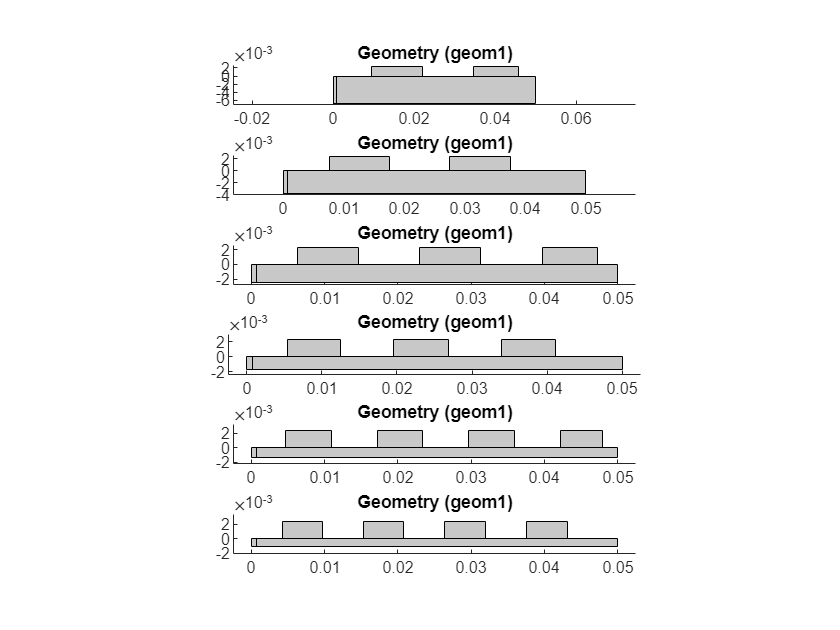

Elapsed time is 42.803205 seconds.


Plate.zSteppedPlateFEM = zeros(length(Study.freqSolid),Study.nMode);
for iMode = 1:Study.nMode
    tic
    if exist('modelComputeSteppedPlateImpedance','var') ~= 1
        modelComputeSteppedPlateImpedance = mphload('computeSteppedPlateImpedance.mph');
    end
    modelComputeSteppedPlateImpedance.hist.disable;
    
    modelComputeSteppedPlateImpedance.param.set('Study_freqStart',   [num2str(Study.FREQ_START)     ' [Hz]']);
    modelComputeSteppedPlateImpedance.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_SOLID)    ' [Hz]']);
    modelComputeSteppedPlateImpedance.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)      ' [Hz]']);
    modelComputeSteppedPlateImpedance.param.set('Plate_t',           [num2str(Plate.tFEM(iMode))    ' [m]']);
    modelComputeSteppedPlateImpedance.param.set('Plate_r',           [num2str(Plate.RADIUS)         ' [m]']);

    tempRStep = cell2mat(Plate.rStepFEM(iMode));
    for iStep = 1:fix(length(tempRStep)/2)  % fix(5/2)=2, fix(6/2)=3
        tag = modelComputeSteppedPlateImpedance.geom('geom1').feature.uniquetag('r');
        modelComputeSteppedPlateImpedance.geom('geom1').feature.create(tag, 'Rectangle');
        modelComputeSteppedPlateImpedance.geom('geom1').feature(tag).set('size', [tempRStep(2*iStep)-tempRStep(2*iStep-1) Plate.tStep]);
        modelComputeSteppedPlateImpedance.geom('geom1').feature(tag).set('pos',  [tempRStep(2*iStep-1) 0]);
    end
    subplot(Study.nMode,1,iMode)
    mphgeom(modelComputeSteppedPlateImpedance)
    drawnow
    mphrun(modelComputeSteppedPlateImpedance,'std1')
    
    Plate.zSteppedPlateFEM(:,iMode) = mphevalpoint(modelComputeSteppedPlateImpedance, '1[N]/solid.u_tZ', 'dataset', 'dset1','selection',1);
    clear modelComputeSteppedPlateImpedance
    toc
end

Plate.zSteppedPlateAcousticFEM = zeros(length(Study.freqAcoustic),Study.nMode);
Aco.tfrSteppedPlateFEM  = zeros(length(Study.freqAcoustic),Study.nMode); % tfr: Transmitting Force Response

% for iMode = 1:1
for iMode = 1:Study.nMode
    tic
    tempFilename = ['computeSteppedPlateAcoustic_r=' num2str(Plate.RADIUS*1e3,'%2.1f')...
        '_t=' num2str(Plate.tFEM(iMode)*1e3,'%2.1f')...
        '_m=' num2str(Study.mode(iMode),'%d')...
        '_f=' num2str(Plate.FREQ/1e3, '%g')...
        '.mph'];
    if exist(tempFilename,'file') == 2
        modelComputeSteppedPlateAcoustic = mphload(tempFilename);
    elseif exist('modelComputeSteppedPlateAcoustic','var') ~= 1
        modelComputeSteppedPlateAcoustic = mphload('computeSteppedPlateAcoustic.mph');
        modelComputeSteppedPlateAcoustic.hist.disable;
        
        modelComputeSteppedPlateAcoustic.param.set('Study_freqStart',   [num2str(Study.FREQ_START)  ' [Hz]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_ACO)   ' [Hz]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)   ' [Hz]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_zStart',      [num2str(Study.Z_START)     ' [m]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_zStop',       [num2str(Study.Z_STOP)      ' [m]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_thStart',     num2str(Study.TH_START));
        modelComputeSteppedPlateAcoustic.param.set('Study_thStop',      num2str(Study.TH_STOP));
        modelComputeSteppedPlateAcoustic.param.set('Plate_t',           [num2str(Plate.tFEM(iMode)) ' [m]']);
        modelComputeSteppedPlateAcoustic.param.set('Plate_r',           [num2str(Plate.RADIUS)      ' [m]']);
    
        tempRStep = cell2mat(Plate.rStepFEM(iMode));
        for iStep = 1:fix(length(tempRStep)/2)  % fix(5/2)=2, fix(6/2)=3
            tag = modelComputeSteppedPlateAcoustic.geom('geom1').feature.uniquetag('r');
            modelComputeSteppedPlateAcoustic.geom('geom1').feature.create(tag, 'Rectangle');
            modelComputeSteppedPlateAcoustic.geom('geom1').feature(tag).set('size', [tempRStep(2*iStep)-tempRStep(2*iStep-1) Plate.tStep]);
            modelComputeSteppedPlateAcoustic.geom('geom1').feature(tag).set('pos',  [tempRStep(2*iStep-1) 0]);
        end
        mphrun(modelComputeSteppedPlateAcoustic,'std1')
        mphsave(modelComputeSteppedPlateAcoustic,[Env.MPH.PATH tempFilename])
    end

    Plate.zSteppedPlateAcousticFEM(:,iMode) = ...
        mphevalpoint(modelComputeSteppedPlateAcoustic, '1[N]/solid.u_tZ', 'dataset', 'dset1','selection',1);
    [Study.z(:,:,iMode), Aco.pcSteppedPlateFEM(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateAcoustic,{'z' 'subst(acpr.efc1.Lp_pext,r,0)'},'dataset','grid1');
    [Study.th(:,:,iMode), Aco.bpSteppedPlateFEM(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateAcoustic,{'th' 'subst(acpr.efc1.Lp_pext,r,sin(th),z,cos(th))'},'dataset','grid2');

    clear modelComputeSteppedPlateAcoustic
    toc
end

Elapsed time is 196.724053 seconds.
Elapsed time is 197.229473 seconds.
Elapsed time is 201.595815 seconds.
Elapsed time is 198.594406 seconds.
Elapsed time is 204.170936 seconds.
Elapsed time is 198.209352 seconds.


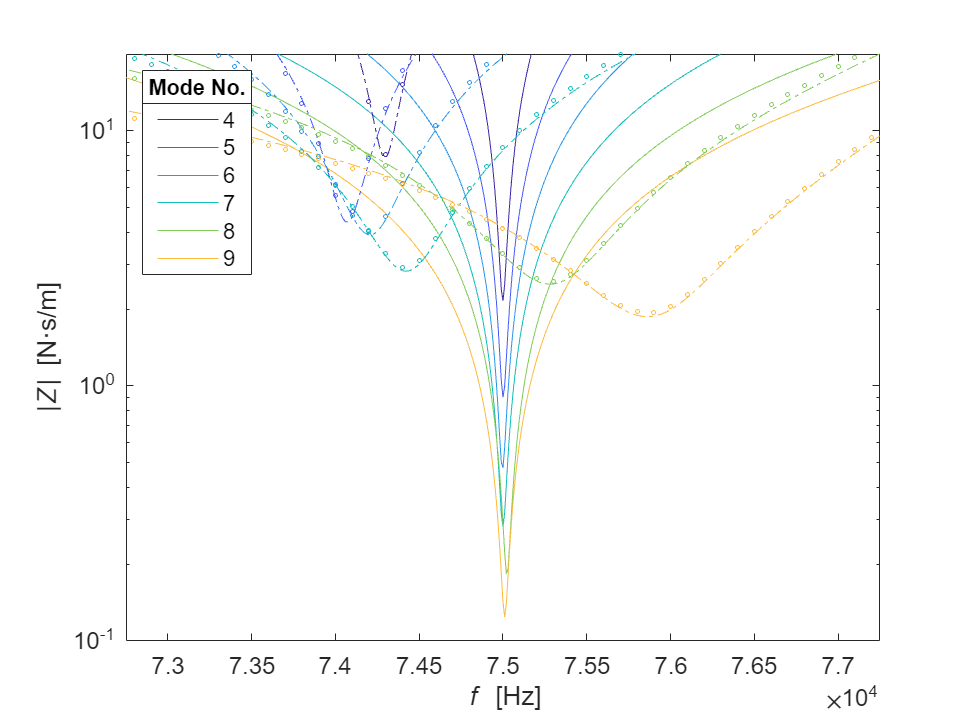

figurePlateImpedance = figure('Name','f vs. Z','Units','inches','Position',[0 0 6.75 5]);

axesPlateImpedance = axes('Parent',figurePlateImpedance);
hold(axesPlateImpedance,'on');
C = colororder(parula(Study.nMode+1));
colororder(C(1:Study.nMode,:));

pPlateImpedance = semilogy(Study.freqSolid, abs(Plate.zPlateFEM));
pSteppedPlateImpedance = semilogy(Study.freqSolid, abs(Plate.zSteppedPlateFEM),'-.');
pSteppedPlateImpedanceAcoustic = semilogy(Study.freqAcoustic, abs(Plate.zSteppedPlateAcousticFEM),'o','MarkerSize',2);

set(axesPlateImpedance,'YMinorTick','on','YScale','log','FontSize',12);
box(axesPlateImpedance,'on');
hold(axesPlateImpedance,'off');
xlabel('{\itf} [Hz]')
ylabel('|{\itZ}| [N·s/m]')
xlim(axesPlateImpedance,[Plate.FREQ*0.97 Plate.FREQ*1.03]);
ylim(axesPlateImpedance,[1e-1 20]);
lgdPlateImpedance = legend(pPlateImpedance, string(Study.MODE_NO_START:Study.MODE_NO_STOP),'Location','northwest','Orientation','vertical');
title(lgdPlateImpedance, 'Mode No.')
hold(axesPlateImpedance,'off');

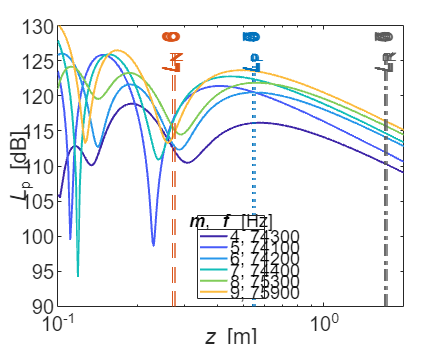

%% TODO: Absorption location

% for a plane circular piston
% Kinsler, L.E., Fundamentals of acoustics / Lawrence E. Kinsler ... [et al.]. 4th ed. 2000, New York: New York : Wiley.
% p.180
Aco.computeRayleighLength       = @(a, f, c) pi*a.^2.*f./c; % S/lambda
Aco.computeAxialPeakDistance    = @(a, f, c) (a.*f./c-c./(4.*f)).* a; % (7.4.10)
Aco.computeAxialNullDistance    = @(a, f, c) (a.*f./(2.*c)-c./(2.*f)).*a; % (7.4.11)

[~,tempI] = min(abs(Plate.zSteppedPlateAcousticFEM),[],1);

figurePropagationCurvePeakFreq = figure('Name','z vs. SPL','Units','inches','Position',[0 0 6.75 5]);

axesPropagationCurvePeakFreq = axes('Parent',figurePropagationCurvePeakFreq);
hold(axesPropagationCurvePeakFreq,'on');
C = colororder(parula(Study.nMode+1));
colororder(repmat(C(1:Study.nMode,:),3,1));

for iMode = 1:Study.nMode
    pPropagationCurvePeakFreqAcoustic = ...
        plot(Study.z(tempI(iMode),:,iMode), Aco.pcSteppedPlateFEM(tempI(iMode),:,iMode), ...
        'DisplayName',[num2str(Study.mode(iMode)) ', ' num2str(Study.freqAcoustic(tempI(iMode)))], ...
        'LineWidth',1);
end

pRayleighLengthPeakFreqAcoustic = xline(Aco.computeRayleighLength(Plate.RADIUS,Study.freqAcoustic(tempI),Air.c),...
    '-.',repmat("{\itL}_R ",1,Study.nMode)'+string(Study.mode)','HandleVisibility','Off','Color','#5C5C5C','LabelHorizontalAlignment','center');
pAxialPeakDistanceFreqAcoustic = xline(Aco.computeAxialPeakDistance(Plate.RADIUS,Study.freqAcoustic(tempI),Air.c),...
    ':',repmat("{\itL}_P ",1,Study.nMode)'+string(Study.mode)','HandleVisibility','Off','Color','#0072BD','LabelHorizontalAlignment','center');
pAxialNullDistanceFreqAcoustic = xline(Aco.computeAxialNullDistance(Plate.RADIUS,Study.freqAcoustic(tempI),Air.c),...
    '--',repmat("{\itL}_N ",1,Study.nMode)'+string(Study.nMode)','HandleVisibility','Off','Color','#D95319','LabelHorizontalAlignment','center');

box(axesPropagationCurvePeakFreq,'on');
hold(axesPropagationCurvePeakFreq,'off');
xlabel('{\itz} [m]')
ylabel('{\itL}_{p} [dB]')
xlim(axesPropagationCurvePeakFreq,[Study.Z_START Study.Z_STOP]);
ylim(axesPropagationCurvePeakFreq,[90 130]);
set(axesPropagationCurvePeakFreq,'XScale','log');
lgdPropagationCurvePeakFreq = legend(axesPropagationCurvePeakFreq,'Location','south','Orientation','vertical');
title(lgdPropagationCurvePeakFreq, '{\itm}{\rm,} {\itf} {\rm[Hz]}')
hold(axesPropagationCurvePeakFreq,'off');

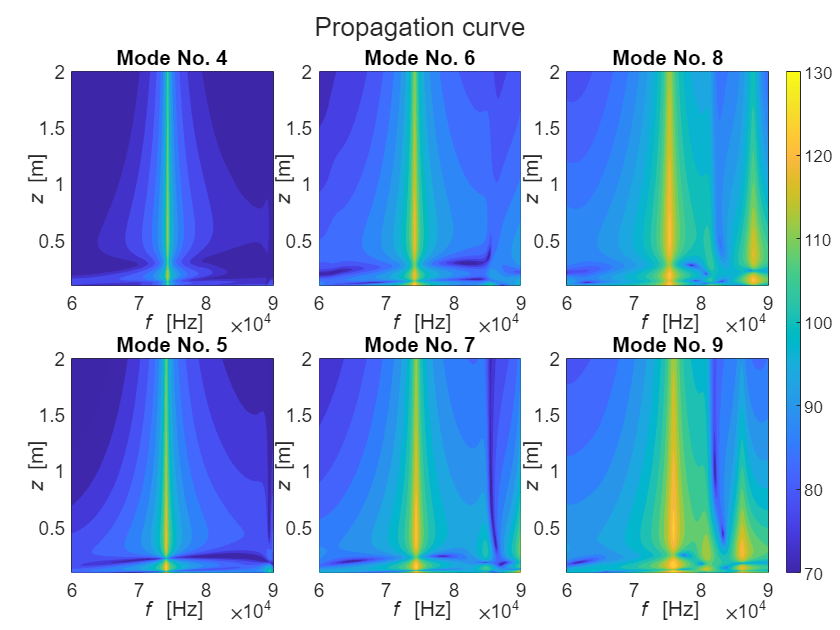

figurePropagationCurve = figure('Name','f, z vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tilePropagationCurve = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
for iMode = 1:Study.nMode
    axesPropagationCurve = nexttile(tilePropagationCurve);
    hold(axesPropagationCurve,'on');
    
    [tempF, tempZ] = meshgrid(Study.freqAcoustic, Study.z(1,:,iMode));
    pPropagationCurve = contourf(tempF, tempZ, ...
        Aco.pcSteppedPlateFEM(:,:,iMode)',20,'EdgeColor','none');
    % pPropagationCurve = contourf(tempF, tempZ, ...
    %     Aco.pcSteppedPlateFEM(:,:,iMode)'-repmat(max(Aco.pcSteppedPlateFEM(:,:,iMode),[],2),1,Study.N_Z)',20,'EdgeColor','none');
    box(axesPropagationCurve,'on');
    hold(axesPropagationCurve,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\itz} [m]')
    title(axesPropagationCurve, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesPropagationCurve,[Study.Z_START Study.Z_STOP]);
    clim(axesPropagationCurve,[70 130]);
    hold(axesPropagationCurve,'off');
end
cbPropagationCurve = colorbar(axesPropagationCurve);
cbPropagationCurve.Layout.Tile = 'east';
title(tilePropagationCurve,'Propagation curve')

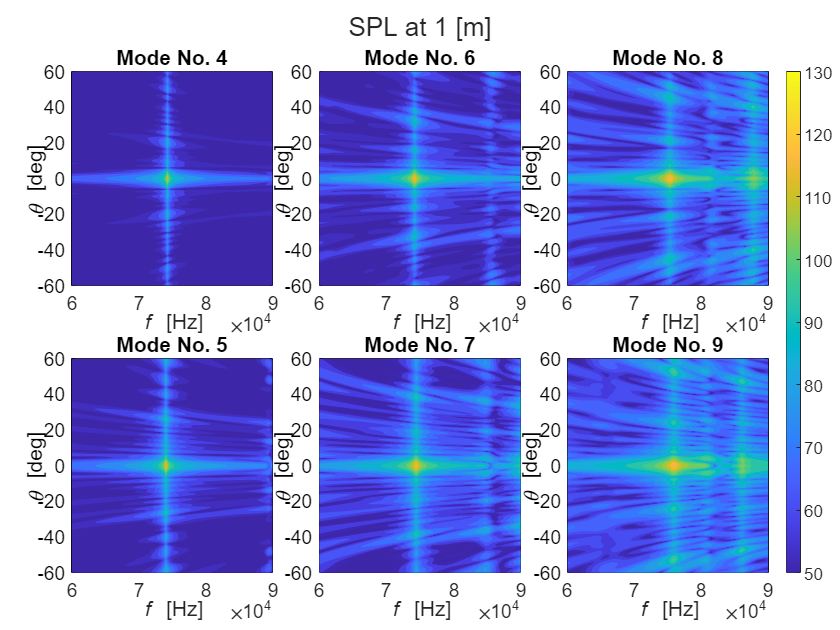

figureBeamPattern = figure('Name','f, th vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tileBeamPattern = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
for iMode = 1:Study.nMode
    axesBeamPattern = nexttile(tileBeamPattern);
    hold(axesBeamPattern,'on');

    [tempF, tempTh] = meshgrid(Study.freqAcoustic, Study.th(1,:,iMode));
    pBeamPattern = contourf(tempF, tempTh/pi*180, ...
        Aco.bpSteppedPlateFEM(:,:,iMode)',20,'EdgeColor','none');

    set(axesBeamPattern,'YColor',[0 0 0]);
    box(axesBeamPattern,'on');
    hold(axesBeamPattern,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\it\theta} [deg]')
    title(axesBeamPattern, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesBeamPattern,[Study.TH_START/pi*180/1.5 Study.TH_STOP/pi*180/1.5]);
    clim(axesBeamPattern,[50 130])
    hold(axesBeamPattern,'off');
end
cbBeamPattern = colorbar(axesBeamPattern);
cbBeamPattern.Layout.Tile = 'east';
title(tileBeamPattern,'SPL at 1 [m]')

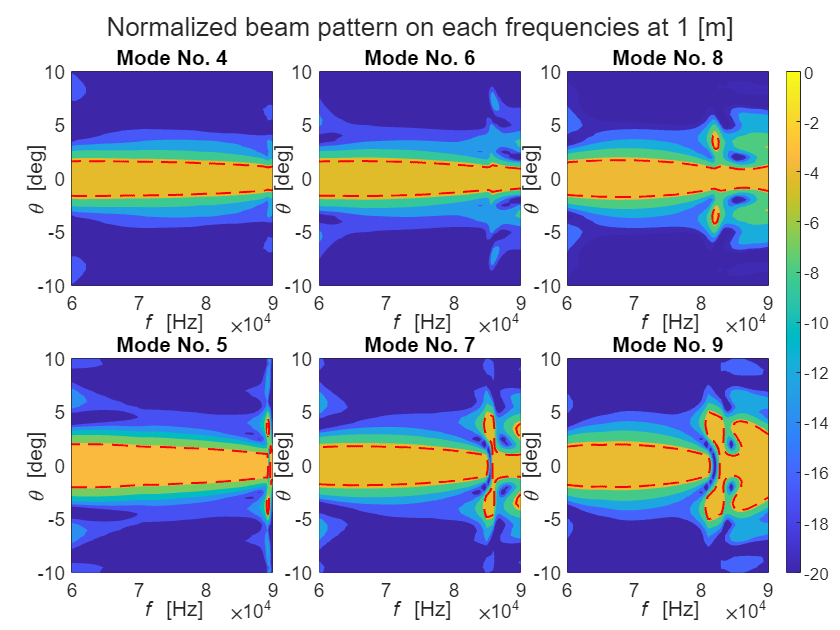

figureBeamPatternNormalized = figure('Name','f, th vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tileBeamPatternNormalized = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
for iMode = 1:Study.nMode
    axesBeamPatternNormalized = nexttile(tileBeamPatternNormalized);
    hold(axesBeamPatternNormalized,'on');
    
    [tempF, tempTh] = meshgrid(Study.freqAcoustic, Study.th(1,:,iMode));
    Aco.bpNormalizedSteppedPlateFEM = Aco.bpSteppedPlateFEM(:,:,iMode)'-repmat(max(Aco.bpSteppedPlateFEM(:,:,iMode),[],2),1,Study.N_TH)';
    pBeamPatternNormalized = contourf(tempF, tempTh/pi*180, ...
        Aco.bpNormalizedSteppedPlateFEM,20,'EdgeColor','none');
    pHalfPowerBeamWidthNormalized = contour(tempF, tempTh/pi*180, ...
        Aco.bpNormalizedSteppedPlateFEM,[-3 -3],'--r','LineWidth',1);

    box(axesBeamPatternNormalized,'on');
    hold(axesBeamPatternNormalized,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\it\theta} [deg]')
    title(axesBeamPatternNormalized, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesBeamPatternNormalized,[Study.TH_START/pi*180/9 Study.TH_STOP/pi*180/9]);
    clim(axesBeamPatternNormalized,[-20 0])
    hold(axesBeamPatternNormalized,'off');
end
cbBeamPatternNormalized = colorbar(axesBeamPatternNormalized);
cbBeamPatternNormalized.Layout.Tile = 'east';
title(tileBeamPatternNormalized,'Normalized beam pattern on each frequencies at 1 [m]')